# Recitation 1

## Exercise 1

clc
clear all
close all

Import known constants

m = 1;                  % mass at end of pendulum
l = 1;                  % length of pendulum
a = 0.5;                % height of attachment of spring/damper
k = 80;                 % spring constant
d = 10;                 % damping constant
I = m*l^2;              % inertia
g = 10;                 % acceleration of gravity

We write the dynamics

f = @(t,x) [x(2) ; g/l * sin(x(1)) - ( a^2 )/(m*l^2) * cos(x(1))*(k*sin(x(1)) + d*cos(x(1))*x(2)) ];

We now solve the system

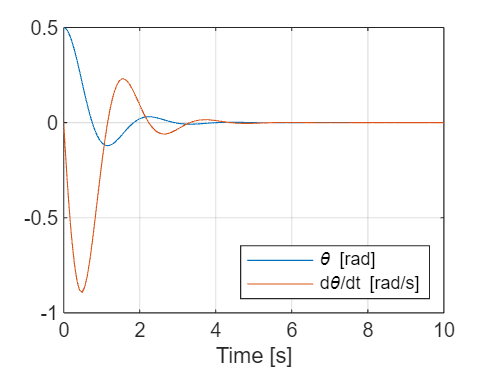

Tf = 10; % final time
x0 = [0.5,0];
[tsim , xsim] = ode45(f,[0,Tf],x0);

figure(1)
plot(tsim,xsim)
xlabel('Time [s]');
legend('\theta [rad]','d\theta/dt [rad/s]','Location','southeast')
grid on

## Exercise 2

xl = [0/180*pi, 0];     % linearization point

fAc = @(xl)    [   0 ,   1;
                    g/l*cos(xl(1))-a^2/(m*l^2)*(...
                        k*(cos(xl(1))^2 - sin(xl(1))^2) ...
                        -2*d*xl(2)*cos(xl(1))*sin(xl(1))), ...
                    -a^2/(m*l^2)*d*cos(xl(1))^2];

fxl = f([],xl);
Ac = fAc(xl);